filename = '/Users/noahday/GitHub/cice-dirs/runs/test/history/iceh_ic.2005-01-01-03600.nc';
ncdisp(filename)

Source:
           /Users/noahday/GitHub/cice-dirs/runs/test/history/iceh_ic.2005-01-01-03600.nc
Format:
           classic
Global Attributes:
           title       = 'sea ice model output for CICE'
           contents    = 'Diagnostic and Prognostic Variables'
           source      = 'Los Alamos Sea Ice Model, CICE_6.2.0'
           comment     = 'All years have exactly 365 days'
           comment2    = 'File written on model date 20050101'
           comment3    = 'seconds elapsed into model date:   3600'
           conventions = 'CF-1.0'
           history     = 'This dataset was created on 2022-06-30 at 15:03:48.1'
           io_flavor   = 'io_netcdf'
Dimensions:
           d2        = 2
           ni        = 360
           nj        = 300
           nc        = 5
           nkice     = 7
           nksnow    = 1
           nkbio     = 3
           nkaer     = 5
           time      = 1     (UNLIMITED)
           nvertices = 4
           nf        = 16
Variables:
    time      

aice = ncread(filename,'aice_d');
lon = ncread(filename,'ULON');
lat = ncread(filename,'ULAT');
tlon = ncread(filename,'TLON');
tlat = ncread(filename,'TLAT');
uatm = ncread(filename,'uatm');


filenamegx1 = 'grid/gx1/global_gx1.bathy.nc';
longx1 = ncread(filenamegx1,'TLON');
latgx1 = ncread(filenamegx1,'TLAT');


f = figure;
w = worldmap('world');
    axesm eqaazim; 
    setm(w, 'Origin', [-90 -90 0]);
    setm(w, 'maplatlimit', [-90,90]);

    setm(w, 'maplonlimit', [0,180]);

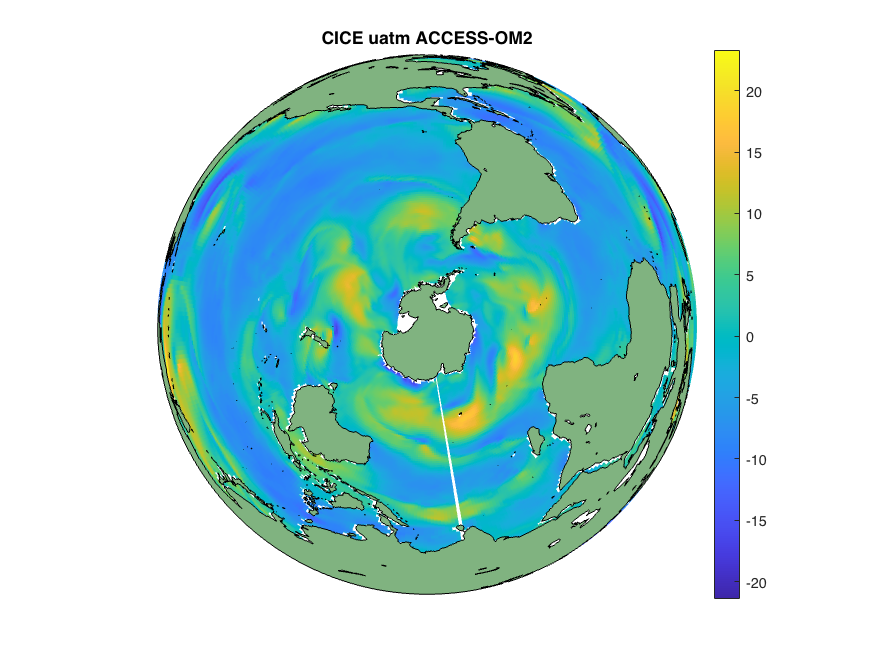

    setm(w, 'meridianlabel', 'off')
    setm(w, 'parallellabel', 'off')
    setm(w, 'grid', 'off');
    setm(w, 'frame', 'off');
    pcolorm(lat,lon,uatm)
    colorbar
    %caxis([-,10])
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    title('CICE uatm ACCESS-OM2')

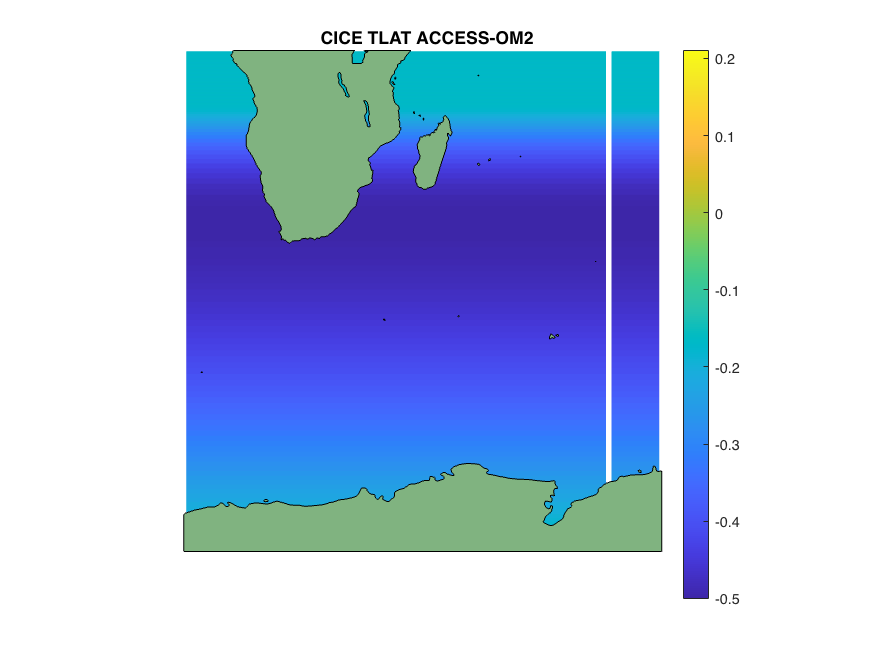


    f = figure;
w = worldmap('world');
    axesm miller; 
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-75,-0]);
    setm(w, 'maplonlimit', [0,90]);
    setm(w, 'meridianlabel', 'off')
    setm(w, 'parallellabel', 'off')
    setm(w, 'grid', 'off');
    setm(w, 'frame', 'off');
    pcolorm(tlat,tlon,tlat-lat)
    colorbar
    %caxis([-,10])
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    title('CICE TLAT ACCESS-OM2')